clear all
close all
clc
path = 'InvestmentReplica.mat';
load(path)
Date_ME = XTab.Date(:, :);

Construct a Monster Index to be replicated

% Synthetic target weights
wHFRXGL = 0.33; 
wMXWO = 0.33;
wLEGATRUU = 0.33;

% Building the target
y = wHFRXGL*price2ret(HFRXGL) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns
target = ret2price(y); % "Monster Index" levels

Check stationarity of the returns

CheckStationarity(y)

    The series is stationary


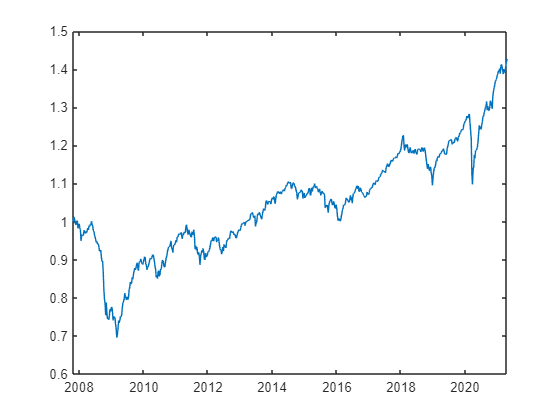

figure
plot(Date_ME,target)

Set of available future for replication

% Futures returns
Futures = [CO1 DU1 ES1 GC1 LLL1 NQ1 RX1 TP1 TU2 TY1 VG1];
X = price2ret(Futures);

for i = 1:size(X,2)
    display(['For the Futures: ',num2str(i)])
    CheckStationarity(X(:,i))
end

For the Futures: 1


    The series is stationary


For the Futures: 2


    The series is stationary


For the Futures: 3


    The series is stationary


For the Futures: 4


    The series is stationary


For the Futures: 5


    The series is stationary


For the Futures: 6


    The series is stationary


For the Futures: 7


    The series is stationary


For the Futures: 8


    The series is stationary


For the Futures: 9


    The series is stationary


For the Futures: 10


    The series is stationary


For the Futures: 11


    The series is stationary


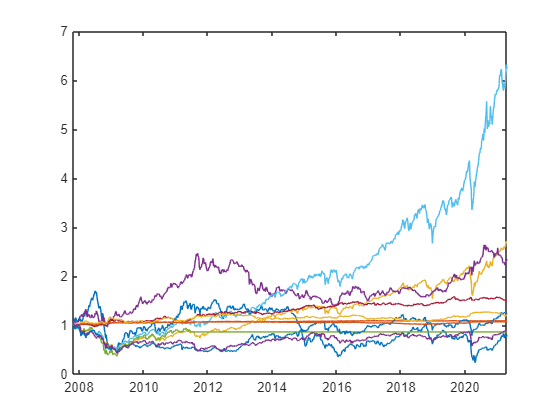

figure
plot(Date_ME,ret2price(X))

Define dimensionalities

% Load the return data
portfolioReturns = y;
futuresReturns = X;

n = size(portfolioReturns, 1);  % Number of time steps
m = size(futuresReturns, 2);    % Number of futures

DA AGGIUNGERE LA PARTE CON LASSO O ELASTIC NET PER FARE UN CONFRONTO BENCHMARK

Compute the weekly weights with Kalmann-Filter

Case with initial x=0.065: TEV_return=0.020639


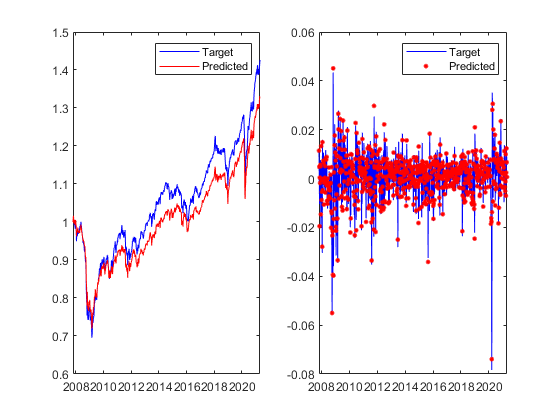

y = portfolioReturns;
% F = eye(m) so it can be omitted
% G = zeros(m) so the associated term is removed
H = futuresReturns;
% D = 0 so the associated term is removed
V1 = eye(m).*std(futuresReturns); 
V2 = std(portfolioReturns); 
% V12 = 0 so the associated term is removed

model = InitializeModel(y, [], [], H, [], V1, V2, []);

x_initial = ones(m,1)*0.065; % empirically obtained, intuitive best solution
[Prediction,TEV_return] = mainKalman(model,x_initial,futuresReturns,Date_ME);

Case with initial x=-0.33333: TEV_return=0.032792


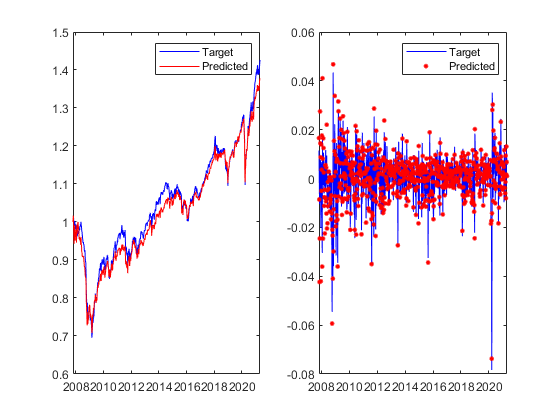

x_initial_temp = [-1/3 1/2 0 1/2 1/3 0 1/3 1/2 -1 1/2 -1/3]'; % to try with different initial values
[Prediction_temp,TEV_return_temp] = mainKalman(model,x_initial_temp,futuresReturns,Date_ME);

Case with initial x=0.090909: TEV_return=0.021184


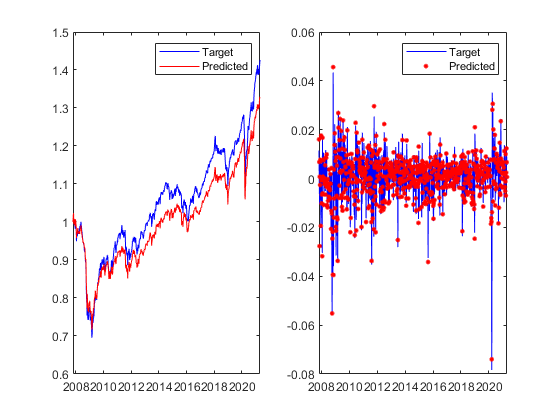

x_initial_temp = ones(m,1)/11; % to try with different initial values
[Prediction_temp,TEV_return_temp] = mainKalman(model,x_initial_temp,futuresReturns,Date_ME);

Statistical meausers

% Gross Total Return, and Excess Return (ER)
logRClone = diff(log(ret2price(Prediction))); 
logRTarget = diff(log(ret2price(y)));
logTE =  logRClone - logRTarget;
meanTRTarget = exp(mean(logRTarget)*52) - 1;
meanTRClone = exp(mean(logRClone)*52) - 1;
meanER = exp(mean(logTE)*52) - 1;
IR = meanER/TEV_return;

display(['Case with initial x= ',num2str(x_initial(1)),': IR= ',num2str(IR)])

Case with initial x= 0.065: IR= -0.24873


% R-squared
% Compute the residual sum of squares (RSS)
RSS = sum((y - Prediction_1).^2);
% Compute the total sum of squares (TSS)
TSS = sum((y - mean(y)).^2);
% Compute R-squared
R_squared_1 = 1 - RSS / TSS;

display(['Case with initial x= ',num2str(x_initial(1)),': R^2= ',num2str(R_squared)])

Case with initial x= 0.065: R^2= 0.92068


DA QUI SI PUO APPROFONDIRE NEL SENSO DI ASSEGNARE UN COSTO PER TRANSAZIONE:

- puo essere costo fisso, ovvero per passare da un peso di 0.3 a 0.6 del future 2 pago X

- oppure per azione, ovvero per ogni singolo future che devo comprare per passare dal peso 0.3 al peso 0.6 pago X, quindi alla fine pago n*X, non sono così sicuro che sia fattibile, probabilmente ci mancano dei dati

Wheights constant in the month as at it beginning

Weights_monthly = Weights_1;
for i = 2:n
    if Date_ME(i).Month == Date_ME(i-1).Month
        Weights_monthly(:,i) = Weights_1(:,i-1);
    else
        Weights_monthly(:,i) = Weights_1(:,i);
    end
end

Prediction_1 = sum(futuresReturns.*Weights_monthly',2);

figure()
plot(Date_ME(2:end),y,'Color','b')
hold on
plot(Date_ME(2:end),sum(futuresReturns.*Weights_monthly',2),'r.','MarkerSize',10)

% Tracking Error = Excess Return = difference between target performance and replica performance.
TE = Prediction_1 - y;
% Tracking Error Volatility = (annualized) standard deviation of Tracking Error.
TEV = std(TE)*sqrt(52)

Find optimal wheights based on Tev

min_TEV = 9999;
for i = 1:n
    TE = sum(futuresReturns*Weights_1(:,i),2) - y;
    TEV = std(TE)*sqrt(52);
    if TEV < min_TEV
        min_TEV = TEV;
        Weights_constant = Weights_1(:,i);
    end
end

Prediction_1 = sum(futuresReturns*Weights_constant,2);

figure()
plot(Date_ME(2:end),y,'Color','b')
hold on
plot(Date_ME(2:end),Prediction_1,'r.','MarkerSize',10)

figure()
plot(Date_ME,target,'Color','b')
hold on
plot(Date_ME,ret2price(Prediction_1),'r.','MarkerSize',1)

% Tracking Error = Excess Return = difference between target performance and replica performance.
TE = Prediction_1 - y;
% Tracking Error Volatility = (annualized) standard deviation of Tracking Error.
TEV = std(TE)*sqrt(52)